# extract and display edges, textures filtering

Read image

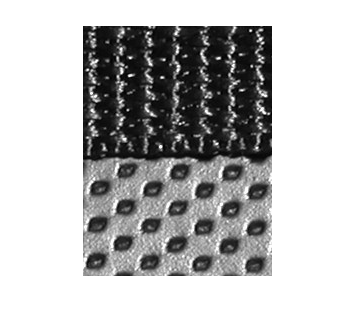

img = imread("bag.png");
imshow(img);

Display edge

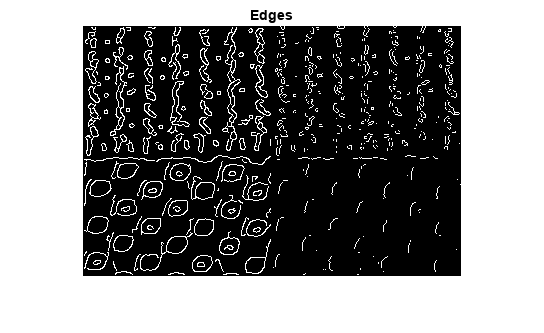

img1 = edge(img, 'canny');
img2 = edge(img, 'prewitt');
imshowpair(img1, img2, 'montage');
title("Edges")

Textures

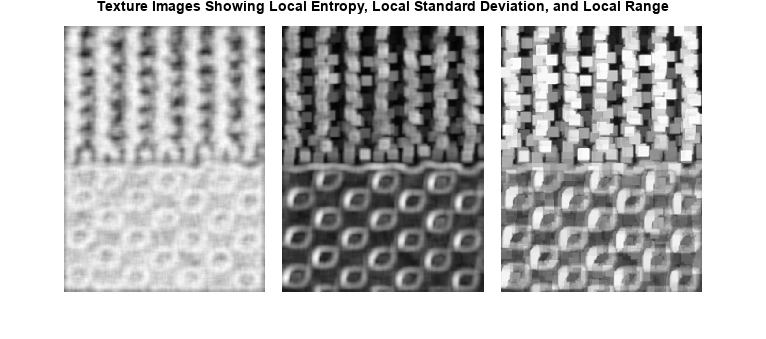

E = entropyfilt(img);
S = stdfilt(img,ones(9));
R = rangefilt(img,ones(9));

Eim = rescale(E);
Sim = rescale(S);

montage({Eim,Sim,R},'Size',[1 3],'BackgroundColor','w',"BorderSize",20);
title('Texture Images Showing Local Entropy, Local Standard Deviation, and Local Range');